# Transformada Hilbert - Huang 

La transformada Hilbert - Huang es una técnica útil para el análisis en frecuencia de señales que provienen de sistemas no estacionarios y no lineales. 

Un ejemplo de sistema de este tipo son aquellos que siguen la ecuación de Duffing:

$\frac{d^2 x}{{\mathrm{dt}}^2 }+\mathrm{kx}\;+\delta \;\frac{\mathrm{dx}}{\mathrm{dt}}+{\mathrm{cx}}^3 =\gamma \;\mathrm{cos}\left(\omega \;t\right)$f

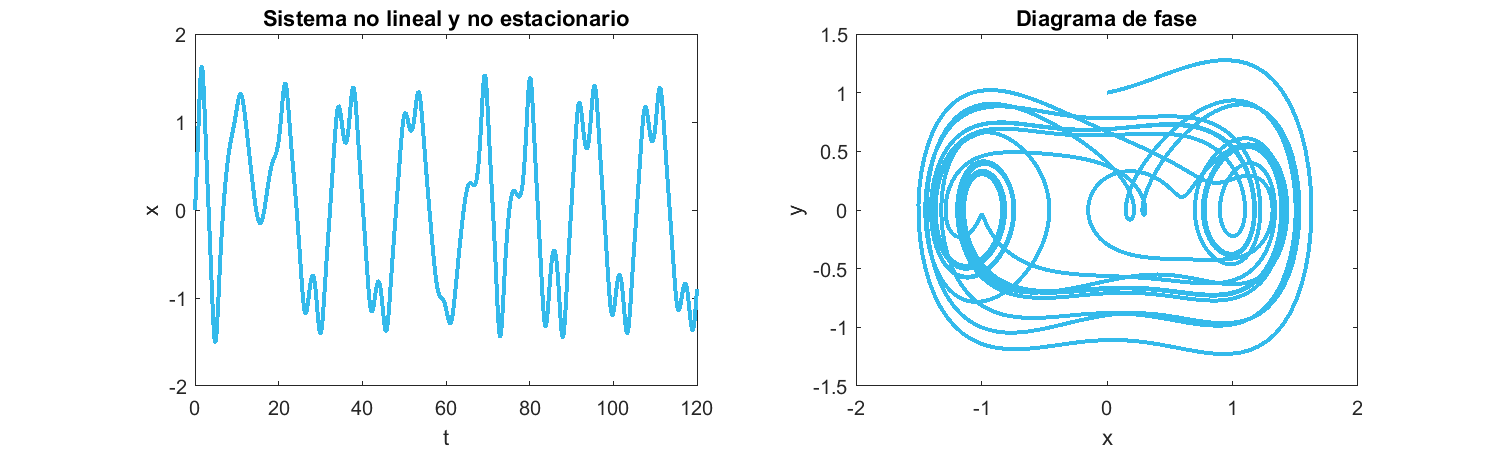

[t,y] = ode45(@duffling, linspace(0,120,2000),[0; 1]);

f = figure();
f.Position = [100 100 1000 300];

subplot(1,2,1)
plot(t,y(:,1), "Color", "#34baeb", "Linewidth", 2)
title("Sistema no lineal y no estacionario")
xlabel("t")
ylabel("x")
subplot(1,2,2)
plot(y(:,1), y(:,2), "Color", "#34baeb", "Linewidth", 2)
title("Diagrama de fase")
xlabel("x")
ylabel("y")

Estas son señales con respuesta no lineal (pueden presentar caos), en las que la frecuencia presenta dependencia temporal con el tiempo  $\omega \;\left(t\right)$.

Hasta este punto del curso contamos con herramientas para analizar:

- Señales estacionarias y lineales: Transformada de Fourier

- Señales no estacionarias y lineales: transformada de fourier de tiempo corto (STFT) y trasnformada Wavelet (CWT y DWT)

Aquí se verá la transformada Hilbert - Huang aplicable con sistemas no estacionarios y no lineales. 

### Pasos de la transformada

- Descomposición de modos intrinsecos

- Aplicación de la transformada de Hilbert

#### 1.- Descomposición de modos intrinsecos

Sea $x\left(t\right)$ la señal a analizar. La primera descomposición $\;c_1 \left(t\right)$, se obtiene de la siguiente forma:

- Se obtienen los mínimos locales de la señal $x\left(t\right)$ y se ajusta una envolvente inferior $m\left(t\right)$ utilizando splines cúbicos.

- Se obtienen los máximos locales de la señal $x\left(t\right)$ y se ajusta una envolvente superior $M\left(t\right)$ utilizando splines cúbicos.

- Se obtiene un promedio de las envolventes $a\left(t\right)=\frac{m\left(t\right)+M\left(t\right)}{2}$

- Se resta dicho promedio de la señal original: $h\left(t\right)=x\left(t\right)-a$(t)

- Repetir el proceso para la señal $h\left(t\right)$

El criterio de paro para el proceso anterior es que hayan transcurrido al menos S iteraciones (número especificado por el usuario), y que:


$$\textrm{ceros}\left(h\left(t\right)\right)\;=\;\textrm{nMinimos}+\textrm{nMaximos}$$


Una vez que se detiene el ciclo el primer nivel de descomposición será


$$c_1 \left(t\right)=h\left(t\right)$$


Un nuevo nivel de descomposición $c_2 \left(t\right)$ puede obtenerse si se repiten los mismos pasos pero para la señal $x\left(t\right)-c_1 \left(t\right)$.

En general el i-ésimo nivel de descomposición se obtendrá aplicando estos pasos con la señal:


$$x\left(t\right)-\sum_{i=1}^{i-1} c_i \left(t\right)$$


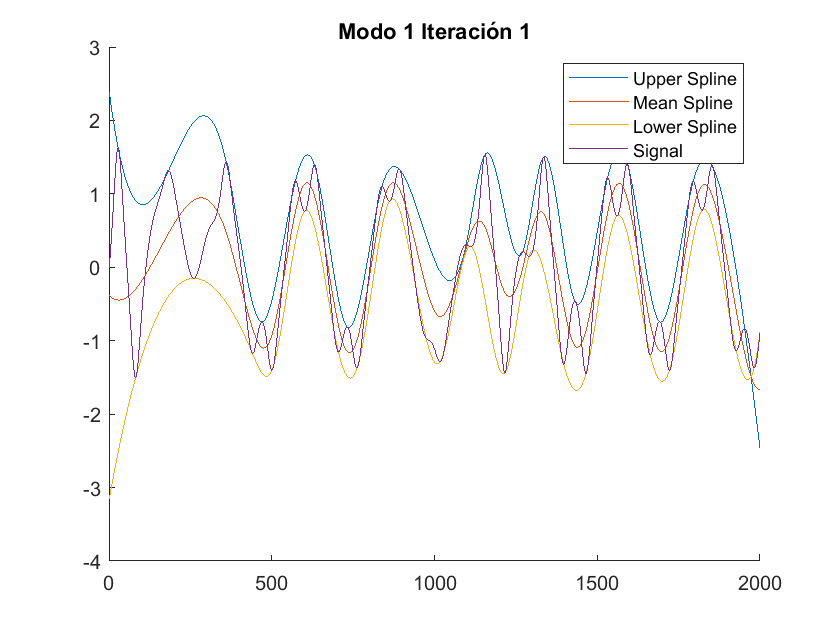

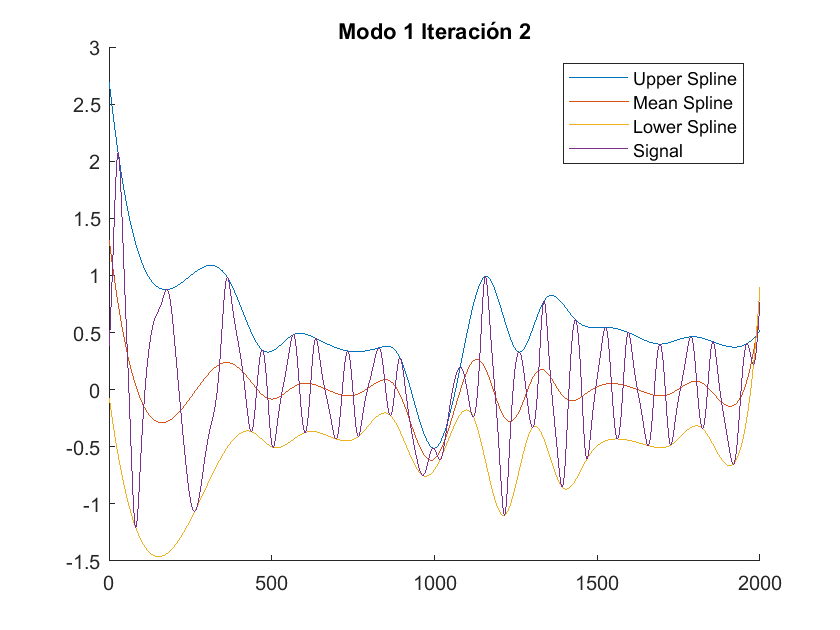

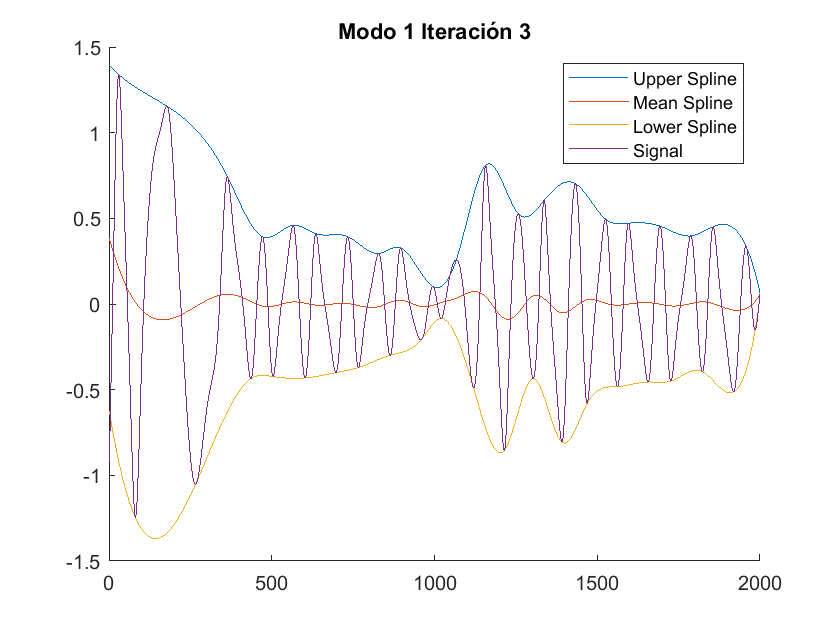

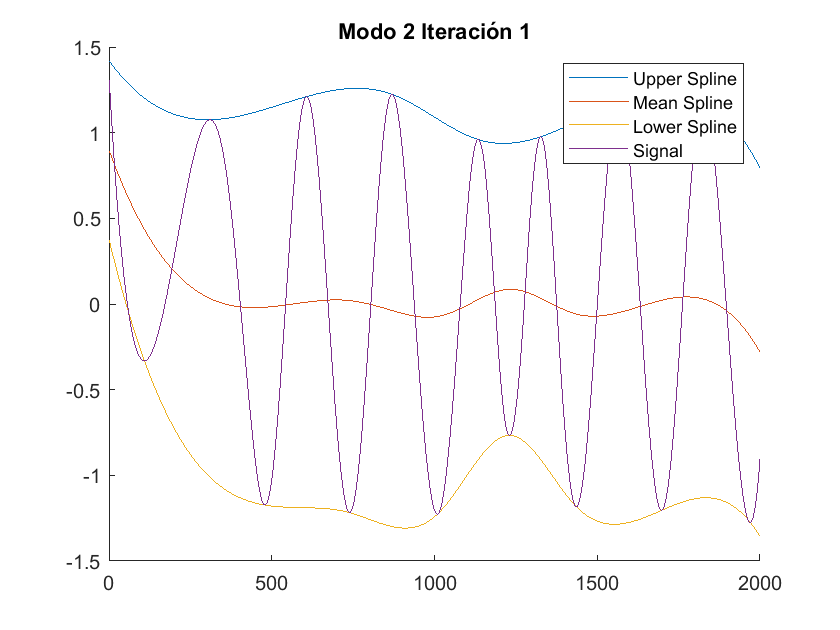

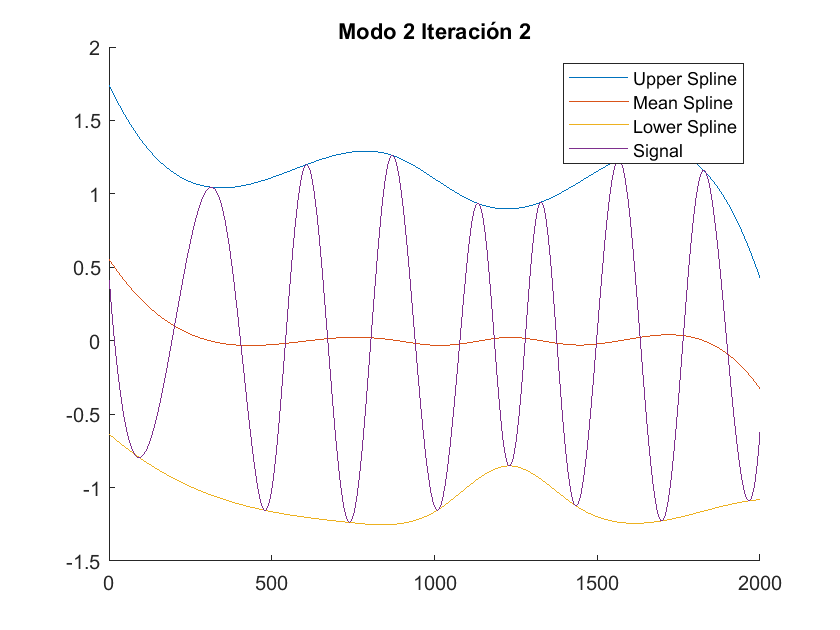

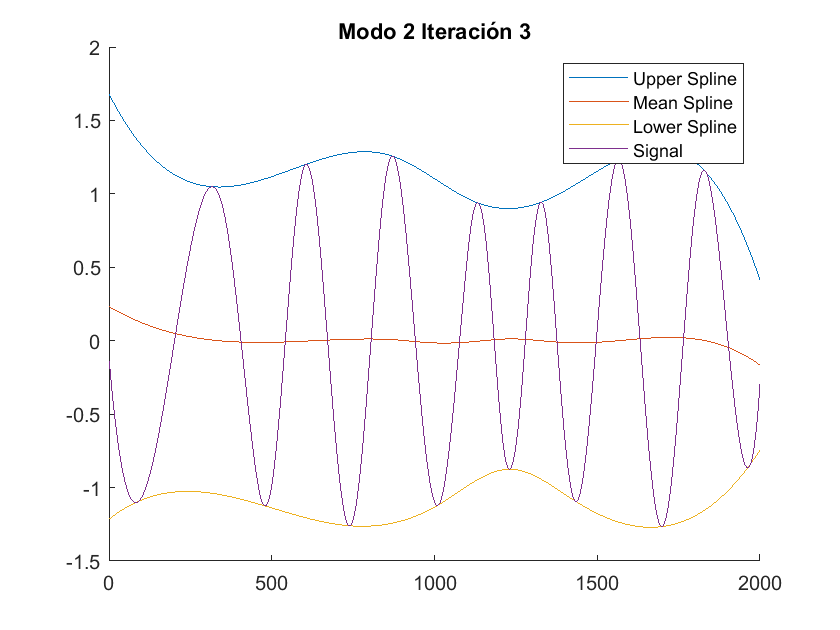


%Apliquemos una descomposición en la señal que acabamos de simular
hilbertHuangTransformer = HilbertHuangTransform();
S = 3;
nLevels = 2;
[modes, residue] = hilbertHuangTransformer.getIntrinsicModeFunctionsWithPlots(y(:,1)', nLevels, S);

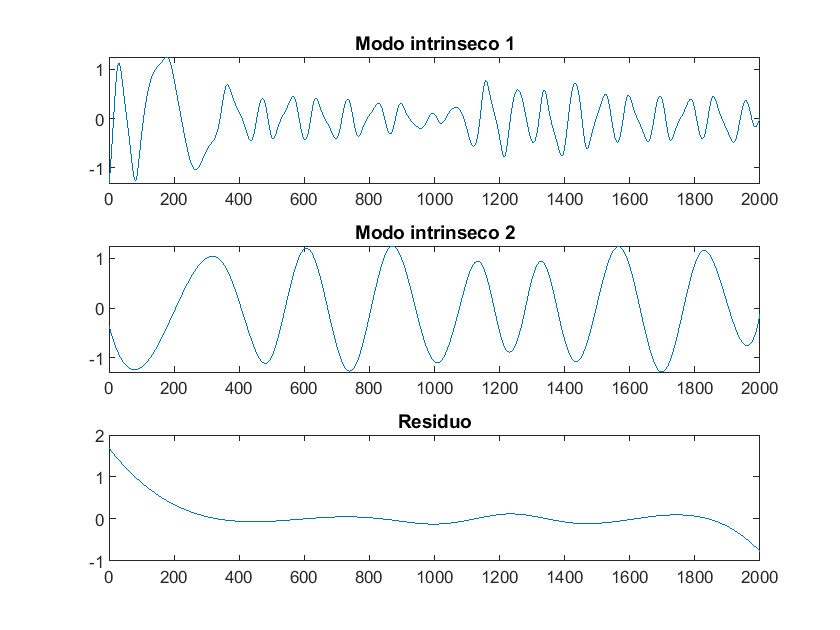

figure()
hold on 
for i = 1:length(modes)
    intrinsicMode = modes{i};
    subplot(length(modes) + 1,1,i);
    plot(intrinsicMode)
    title("Modo intrinseco "+string(i))
end

subplot(length(modes) +1,1,length(modes) + 1)
plot(residue)
title("Residuo")

Para reconstruir la señal se suma el residuo y los distintos modos intrinsecos:


$$x\left(t\right)=r\left(t\right)+\sum_i c_i \left(t\right)$$


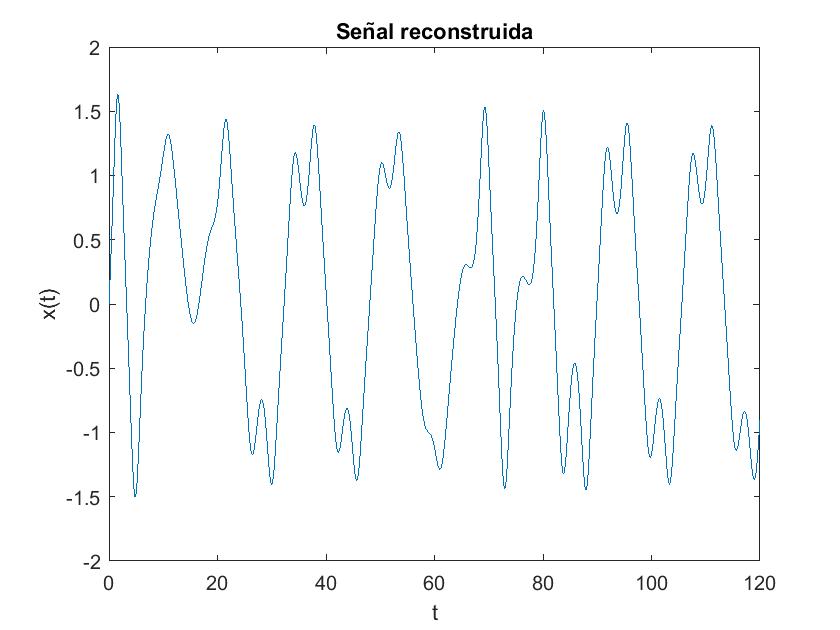

reconstructedSignal = hilbertHuangTransformer.reconstructSignal(residue, modes);

figure()
plot(t, reconstructedSignal)
title("Señal reconstruida")
xlabel("t")
ylabel("x(t)")

#### 2.- Transformada Hilbert. 

La siguiente parte consiste en obtener la transformada de Hilbert de los modos intrínsecos. 

Sea $H\left(c_i \left(t\right)\right)$la transformada del i-ésimo modo. 

Lo que hacemos es considerar a esta transformada como la parte imaginaria de una función compleja, es decir formamos:


$$z_i \left(t\right)=c_i \left(t\right)+H\left(c_i \left(t\right)\right)\;j$$
 

Ahora, esta función compleja la podriamos escribir usando la identidad de Euler en terminos de magnitud y fase. 


$$z_i \left(t\right)={a_i \left(t\right)e}^{j\phi_i \left(t\right)}$$


Ahora, como $\phi \left(t\right)=\omega \;j$

Se puede obtener la frecuencia instantanea derivando la fase. 


$$\omega_i =\frac{\;d\phi_i \;}{\mathrm{dt}}$$


Una vez que se cuenta con los arreglos de frecuencia $\omega_i \left(t\right)$ y amplitud $a_i \left(t\right)$ para una componente dada se puede obtener el espectro de Hilbert mediante la siguiente relación:


$$H_i \left(\omega \;,t\right)\left\lbrace \begin{array}{ll}
a_i \left(t\right) & \omega =\omega {\;}_i \left(t\right)\\
0 & \mathrm{de}\;\mathrm{otra}\;\mathrm{forma}
\end{array}\right.$$


El espectro completo se obtiene sumando los espectros de cada componente


$$H\left(\omega ,t\right)=\sum_{i=1}^n H_j \left(\omega ,t\right)$$


%Probemos nuestra función 
deltaT = t(2) - t(1);
Fs = 1/deltaT;
[freqs, times, hilbertSpectrum] = hilbertHuangTransformer.getHilbertSpectrum(y(:,1)',2,4,Fs,200);

Min frequency -0.9041
Max frequency 2.8805


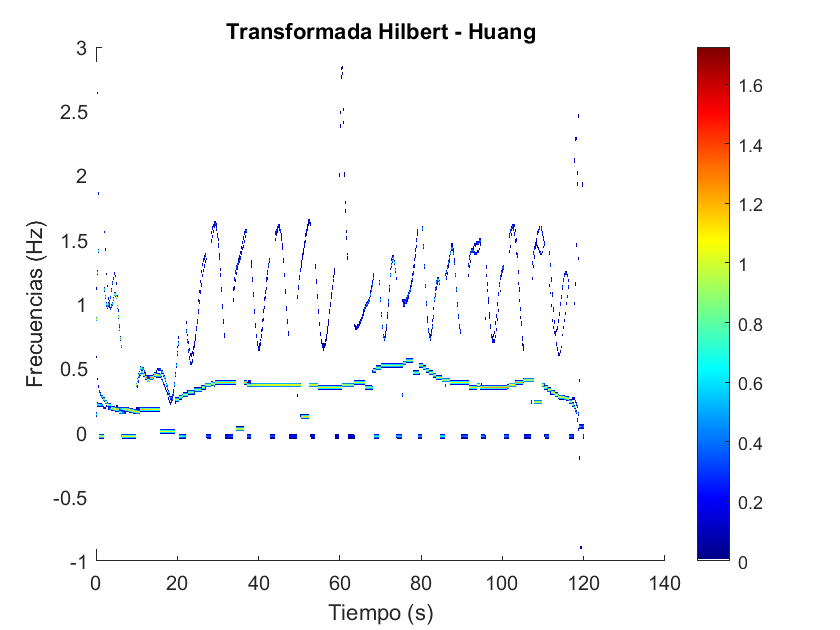


figure()
hold on 
s = pcolor(times, freqs, hilbertSpectrum);
s.FaceColor = "interp";
s.EdgeColor = "none";
xlabel("Tiempo (s)")
ylabel("Frecuencias (Hz)")
title("Transformada Hilbert - Huang")
myColorMap = jet(256);
myColorMap(1,:) = 1;
colormap(myColorMap);
colorbar
hold off

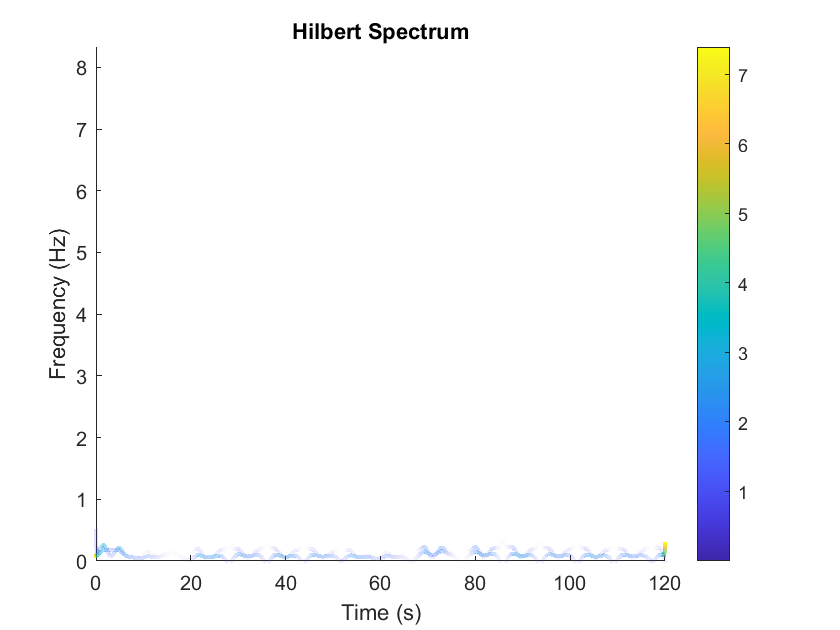


hht(y, Fs)

function dydt = duffling(t, y)
gamma = 0.50;
k = -1;
omega = 1.2;
delta = 0.3;
c = 1;
dydt = [y(2) ; gamma*cos(omega*t) - k*y(1) - delta*y(2) - c*y(1)^3];
end